# **Digital Communications TTT4130 - Matlab Lab Sessions**

**Lab Responsible**: Johan Suarez (johan.suarez@ntnu.no)

`Prerequisites`

Up-to-date installation of `MATLAB `and `SIMULINK `including `Communications Toolbox. (NTNU students receive Campus license)`

`Instructions`

**All lab sessions are group projects. Groups will be assigned randomly and consist of 2-3 people.** 

This is a Matlab live script. The script will guide through the lab session with coding tasks accompanied by explanations and comments.

**Please download and install MATLAB/Simulink and include the Communications toolbox as add-in. **

**You are free to use any resource you think is useful. Collaboration and discussion between groups is encouraged. **

# `Project 3 - Channel Coding`

### `Digital Communication System Schematic`

# 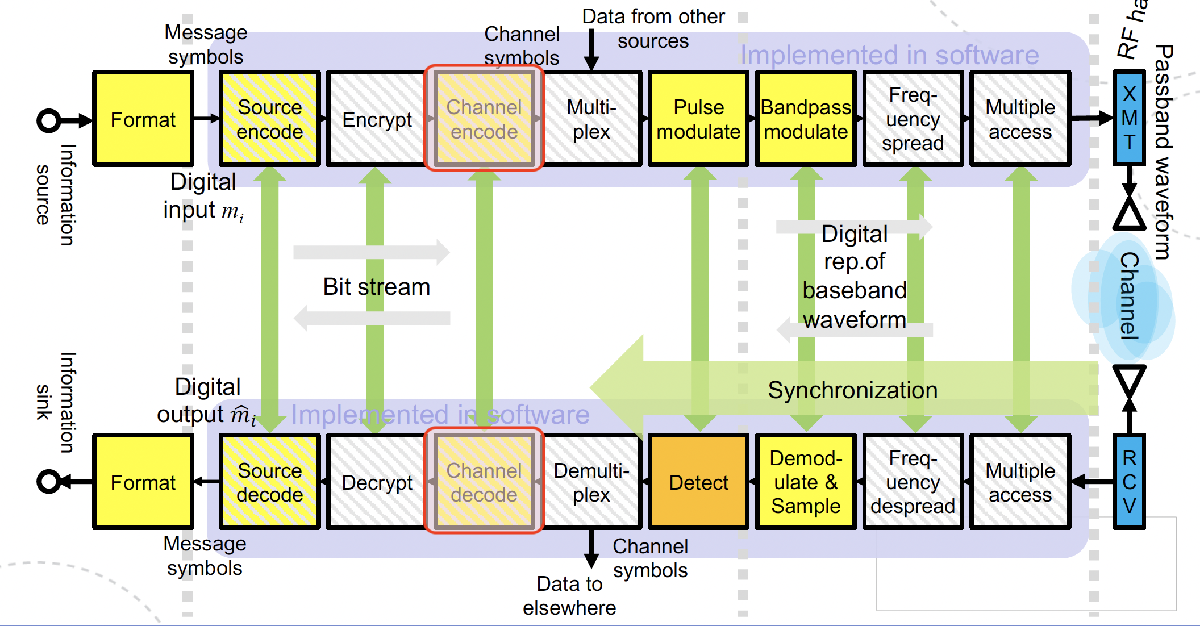

Specifically, the lab session covers the highlighted (red) parts of the schematic depicted above. 

### `Course Content`

- Coding Gain

- Convolutional Codes

- Cyclic redundancy check

- Bit interleaved coded modulation

#### `Task 1 : Hamming Code`

This task illustrates the principle of *block codes*. 

- Generator Matrix

- Parity Check Matrix

- Syndrome

Recomended reading: Section 6.4 *Linear Block Codes *in *Digital Communications, Sklar*

% Tip: Use MatLab inbuilt functions whenever possible 


% Define message length k and codeword length n 
n = 7; k = 4;     

% Generate random binary message of length k
data = randi([0 1], k, 1)';


% Generate parity check matrix and generator matrix using hammgen()
[H, G, n, k] = hammgen(3);

% Encode the message using encode()
enc_data = encode(data, n, k);
%  Use the first column of the codes STANDARD ARRAY to construct the error
%  pattern -> syndrome LUT
LUT = containers.Map( ...
    'keyType', 'char', ...
    'ValueType', 'any');
e = zeros(1, n);
s = mod(H * e', 2);
LUT(num2str(s')) = e;

for i = 1:n
    e = zeros(1,n);
    e(i) = 1;
    s = mod(H * e', 2);
    LUT(num2str(s')) = e;
end
% Introduce 1-bit errors at different positions in the codeword and calculate the
% syndrome of the error
receiveBit = enc_data;
flipBit = 3;

% Flip 1 bit
receiveBit(flipBit) = mod(receiveBit(flipBit) + 1, 2);

% Decode using created LUT & check if 1-bit error can be successfully
% decoded
s_bit = mod(H * receiveBit',2 );
num2str(s_bit);
e_hat = LUT(num2str(s_bit'));
correctBit = mod(receiveBit + e_hat, 2);
decoded_1bit = correctBit(logical(sum(G, 1) == 1));                                                      
  fprintf('Original data:     %s\n', num2str(data));   

Original data:     1  1  0  0


  fprintf('Sendt bit:       %s\n', num2str(receiveBit));

Sendt bit:       1  0  0  1  1  0  0


  fprintf('Decoded (1-bit):   %s\n', num2str(decoded_1bit));                                                     

Decoded (1-bit):   1  1  0  0


  fprintf('1-bit error corrected: %d\n', isequal(data, decoded_1bit));

1-bit error corrected: 1


% ------------------------------------------------- %

% Flip 2 bits at different positions and check if the erraneous codeword
% can be successfully decoded
recivedData2 = enc_data;
recivedData2(2) = mod(recivedData2(2) + 1, 2);
recivedData2(5) = mod(recivedData2(5) + 1, 2);

s_bit = mod(H * recivedData2', 2)

s_bit =      0
     0
     1


e_hat = LUT(num2str(s_bit'))

e_hat =      0     0     1     0     0     0     0


corrected2 = mod(recivedData2 + e_hat, 2);
decoded2 = corrected2(logical(sum(G,1) == 1))

decoded2 =      1     0     0     0


fprintf('2-bit error corrected: %d\n', isequal(data, decoded2));      

2-bit error corrected: 0



data

data =      1     1     0     0


% Decode with Matlab inbuilt functions and confirm your findings from above
 decoded_builtin = decode(recivedData2, n, k);                                                                                                                
 fprintf('Decoded (built-in): %s\n', num2str(decoded_builtin)); 

Decoded (built-in): 1  0  0  0


 fprintf('Decoder (built-in) vs decoder (self-made): %d\n', isequal(decoded_builtin, decoded2));  

Decoder (built-in) vs decoder (self-made): 1


#### `Task 2 : Convolutional Encoder & Decoder`

- Convolutional Encoding

- Convolutional Code Parameters

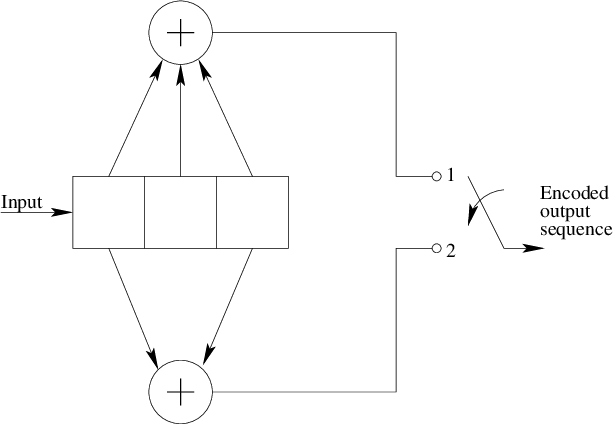

Determine the convolutional coding parameters from the schematic above. Then implement the convolutional encoder for a binary sequence of your choice. 

If you decide to use a non continous message bit stream (i.e., a message of specific length) *flush *the registers. 

*(refer to p. 378ff Digital Communcations, Sklar)*

%% Task 2 – Convolutional Encoder & Viterbi Decoder
clear; clc;

K       = 3;
trellis = poly2trellis(K, [7 5]);
tblen   = 5 * K;

msg = randi([0 1], 1, 100);

msg_flushed = [msg, zeros(1, K-1)];
enc = convenc(msg_flushed, trellis);
enc = enc(:)';

tx = 1 - 2*double(enc);
noise_std = 0.8;   
rx = tx + noise_std * randn(size(tx));
fprintf('Bit errors before decoding: %d / %d\n', ...
    sum(double(rx < 0) ~= enc), length(enc));

Bit errors before decoding: 17 / 204




% Hard decision Viterbi 
n_sym      = length(rx) / 2;
tblen_safe = min(tblen, n_sym);

dec_hard = vitdec(double(rx < 0), trellis, tblen_safe, 'trunc', 'hard');
dec_hard = dec_hard(1:length(msg));
fprintf('Bit errors after hard Viterbi: %d / %d\n', sum(msg ~= dec_hard), length(msg));

Bit errors after hard Viterbi: 6 / 100



% Soft decision Viterbi 
dec_soft = vitdec(softQuantize(rx, 3), trellis, tblen_safe, 'trunc', 'soft', 3);
dec_soft = dec_soft(1:length(msg));
fprintf('Bit errors after soft Viterbi: %d / %d\n', sum(msg ~= dec_soft), length(msg));

Bit errors after soft Viterbi: 0 / 100



% Helper
function q = softQuantize(rx, nsdec)
    levels     = 2^nsdec - 1;
    clip       = 3.0;
    rx_clipped = max(-clip, min(clip, rx));
    q          = round((1 - rx_clipped/clip) / 2 * levels);
    q          = max(0, min(levels, q));
end


#### `Task 3 : Cyclic Redundancy Check - CRC`

Now use a CRC encoder on your message.

Obtain an estimate for the error detection capability of the CRC, i.e. what is the probability of missed error detection of the CRC, and the overhead introduced.

%% Task 3 – Cyclic Redundancy Check (CRC)
clear; clc;

%% Parameters
msg_len  = 100;
crc_poly = [1 0 0 1 1];        % CRC-4: generates 4 parity bits
crcGen   = comm.CRCGenerator(crc_poly);
crcDet   = comm.CRCDetector(crc_poly);

msg     = randi([0 1], msg_len, 1);
msg_crc = crcGen(msg);          % append CRC bits

fprintf('Original length:      %d bits\n', length(msg));

Original length:      100 bits


fprintf('Length after CRC:     %d bits\n', length(msg_crc));

Length after CRC:     104 bits



crc_bits         = length(msg_crc) - length(msg);
overhead_fraction = crc_bits / length(msg);
fprintf('CRC bits added:       %d\n',    crc_bits);

CRC bits added:       4


fprintf('CRC overhead:         %.2f%%\n', 100 * overhead_fraction);

CRC overhead:         4.00%



% Introduce random bit errors directly on the CRC-encoded message
flip_prob     = 0.02;
rx            = msg_crc;
error_pos     = rand(size(rx)) < flip_prob;
rx(error_pos) = ~rx(error_pos);

[~, crc_error] = crcDet(rx);
if crc_error == 0
    disp('Single example: CRC passed (no error detected).');
else
    disp('Single example: CRC failed (error detected).');
end

Single example: CRC failed (error detected).



% Testing with Monte carlo 
num_trials        = 10000;
num_error_events  = 0;
num_missed        = 0;

for t = 1:num_trials
    msg     = randi([0 1], msg_len, 1);
    msg_crc = crcGen(msg);

    rx        = msg_crc;
    error_pos = rand(size(rx)) < flip_prob;
    rx(error_pos) = ~rx(error_pos);

    if any(rx ~= msg_crc)
        num_error_events = num_error_events + 1;


        [~, crc_error] = crcDet(rx);
        if crc_error == 0
            num_missed = num_missed + 1;
        end
    end
end

if num_error_events > 0
    P_missed = num_missed / num_error_events;
else
    P_missed = 0;
end

fprintf('\n--- CRC performance (Monte Carlo, %d trials) ---\n', num_trials);


--- CRC performance (Monte Carlo, 10000 trials) ---


fprintf('Error events:               %d\n',   num_error_events);

Error events:               8755


fprintf('Missed detections:          %d\n',   num_missed);

Missed detections:          383


fprintf('P(missed detection):        %.6f\n', P_missed);

P(missed detection):        0.043746


fprintf('Theoretical lower bound:    %.6f\n', 2^(-crc_bits));

Theoretical lower bound:    0.062500


`Task 4: Interleaving`

Realise a system that utilises convolutional coding and eventually cyclic redundancy checks to correct and detect errors in transmission.

ocument the minimum separation achieved by the interleaver.

function BER = task4_ber(EbN0_dB, n_trials)
    %% Parameters
    msg_len     = 100;

Bit error rate 5dB:          8.680000e-02


    K           = 3;

Bit error rate 10dB:          7.000000e-04


    trellis     = poly2trellis(K, [7 5]);
    tblen       = 5 * K;
    M           = 16;
    bps         = log2(M);
    interl_rows = 10;
    crcGen      = comm.CRCGenerator([1 0 0 1 1]);
    crcDet      = comm.CRCDetector([1 0 0 1 1]);

    n_crc       = msg_len + 4;
    n_enc       = 2 * n_crc;
    n_padded    = ceil(n_enc / (interl_rows * bps)) * (interl_rows * bps);
    interl_cols = n_padded / interl_rows;

    %% Loop over SNR values
    BER = zeros(size(EbN0_dB));

    for idx = 1:length(EbN0_dB)
        err_bits = 0;

        for trial = 1:n_trials

            % 1. Message
            msg = randi([0 1], msg_len, 1);

            % 2. CRC
            msg_crc = crcGen(msg);

            % 3. Convolutional encode
            msg_flushed = [msg_crc', zeros(1, K-1)];
            enc = convenc(msg_flushed, trellis);
            enc = enc(1:n_enc);

            % 4. Interleave
            enc_padded  = [enc, zeros(1, n_padded - n_enc)];
            mat_tx      = reshape(enc_padded, interl_cols, interl_rows);
            interleaved = reshape(mat_tx', 1, []);

            % 5. 16-QAM modulate
            sym_idx = bi2de(reshape(interleaved, bps, [])', 'left-msb');
            tx_syms = qammod(sym_idx, M, 'gray', 'InputType', 'integer', ...
                             'UnitAveragePower', true);

            % Channel
            SNR_sym_dB = EbN0_dB(idx) + 10*log10(bps * 0.5);
            rx_syms    = awgn(tx_syms, SNR_sym_dB, 'measured');

            % 6. Demodulate
            rx_idx  = qamdemod(rx_syms, M, 'gray', 'OutputType', 'integer', ...
                               'UnitAveragePower', true);
            rx_bits = reshape(de2bi(rx_idx, bps, 'left-msb')', 1, []);

            % 7. De-interleave
            mat_rx   = reshape(rx_bits, interl_rows, interl_cols);
            deinterl = reshape(mat_rx', 1, []);
            deinterl = deinterl(1:n_enc);

            % 8. Viterbi
            dec = vitdec(deinterl, trellis, tblen, 'trunc', 'hard');
            dec = dec(1:n_crc)';

            % 9. CRC check
            [recovered, ~] = crcDet(dec);

            % 10. BER
            err_bits = err_bits + sum(recovered ~= msg);
        end

        BER(idx) = err_bits / (n_trials * msg_len);
    end
end

Check BER at 10dB, and 5dB

snr = [5, 10];
BER = task4_ber(snr, 100);
fprintf('Bit error rate 5dB:          %d\n',   BER(1));
fprintf('Bit error rate 10dB:          %d\n',   BER(2));

#### `Task 5: Coding Gain`

Compare the BER vs SNR performance of     

- Hamming codes

- Convolutional codes w/ hard-, and soft decoding

This is an unguided exercises. It is recommended to use Matlab inbuilt functions wherever possible. 

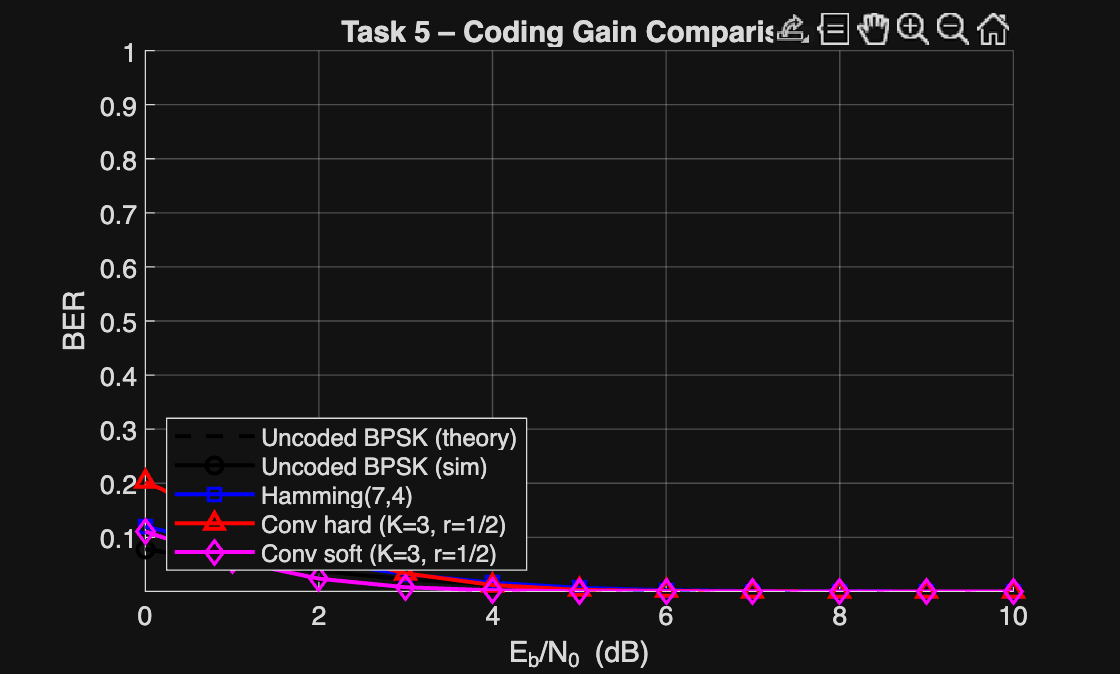

% Implementation
%% Task 5 – Coding Gain: BER vs SNR comparison
% Compares: uncoded BPSK, Hamming(7,4), Conv hard, Conv soft
clear; clc;

%% Shared parameters
EbN0_dB_vec = 0:1:10;
n_trials    = 200;
msg_len     = 1000;        % bits per trial (multiple of 4 for Hamming)

%% Convolutional parameters (reused from Task 2)

K       = 3;
trellis = poly2trellis(K, [7 5]);
tblen   = 5 * K;

--- Approximate coding gain at BER ~ 1e-3 ---



%% Hamming(7,4) parameters
n_ham = 7; k_ham = 4;
[H_ham, G_ham] = hammgen(3);

%% Result arrays
BER_uncoded   = zeros(size(EbN0_dB_vec));
BER_hamming   = zeros(size(EbN0_dB_vec));
BER_conv_hard = zeros(size(EbN0_dB_vec));
BER_conv_soft = zeros(size(EbN0_dB_vec));

%% --- SNR sweep ---
for idx = 1:length(EbN0_dB_vec)
    EbN0_dB  = EbN0_dB_vec(idx);
    EbN0_lin = 10^(EbN0_dB / 10);

    err_uncoded   = 0;
    err_hamming   = 0;
    err_conv_hard = 0;
    err_conv_soft = 0;
    tot_uncoded   = 0;
    tot_hamming   = 0;
    tot_conv      = 0;


  Uncoded (sim)         SNR @ BER=1e-3:  6.77 dB   Coding gain: +0.00 dB
  Hamming(7,4)          SNR @ BER=1e-3:  6.68 dB   Coding gain: +0.09 dB
  Conv hard             SNR @ BER=1e-3:  5.81 dB   Coding gain: +0.96 dB
  Conv soft             SNR @ BER=1e-3:  4.35 dB   Coding gain: +2.42 dB


    for trial = 1:n_trials

        %% === UNCODED BPSK ===
        msg_u  = randi([0 1], 1, msg_len);
        tx_u   = 1 - 2*msg_u;                          % BPSK: 0→+1, 1→-1
        % noise std for uncoded BPSK: sigma = 1/sqrt(2*Eb/N0)
        rx_u   = tx_u + randn(size(tx_u)) / sqrt(2 * EbN0_lin);
        dec_u  = double(rx_u < 0);
        err_uncoded = err_uncoded + sum(dec_u ~= msg_u);
        tot_uncoded = tot_uncoded + msg_len;

        %% === HAMMING(7,4) ===
        % msg length must be multiple of k_ham=4
        msg_h   = randi([0 1], 1, msg_len);
        % Encode block by block
        n_blocks  = floor(msg_len / k_ham);
        msg_trim  = msg_h(1 : n_blocks * k_ham);
        enc_h     = zeros(1, n_blocks * n_ham);
        for b = 1:n_blocks
            blk = msg_trim((b-1)*k_ham+1 : b*k_ham);
            enc_h((b-1)*n_ham+1 : b*n_ham) = encode(blk, n_ham, k_ham, 'hamming/binary');
        end
        % Hamming code rate = 4/7
        % noise std: sigma = sqrt(n_ham / (k_ham * 2 * EbN0_lin))
        noise_std_h = sqrt(n_ham / (k_ham * 2 * EbN0_lin));
        tx_h = 1 - 2*enc_h;
        rx_h = tx_h + noise_std_h * randn(size(tx_h));
        rx_hard_h = double(rx_h < 0);
        % Decode block by block
        dec_h = zeros(1, n_blocks * k_ham);
        for b = 1:n_blocks
            blk_rx = rx_hard_h((b-1)*n_ham+1 : b*n_ham);
            dec_h((b-1)*k_ham+1 : b*k_ham) = decode(blk_rx, n_ham, k_ham, 'hamming/binary');
        end
        err_hamming = err_hamming + sum(dec_h ~= msg_trim);
        tot_hamming = tot_hamming + n_blocks * k_ham;

        %% === CONVOLUTIONAL – hard & soft ===
        msg_c      = randi([0 1], 1, msg_len);
        msg_flush  = [msg_c, zeros(1, K-1)];
        enc_c      = convenc(msg_flush, trellis);
        enc_c      = enc_c(:)';
        tx_c       = 1 - 2*double(enc_c);
        % Conv code rate = 1/2
        % noise std: sigma = sqrt(1 / (2 * 0.5 * EbN0_lin)) = sqrt(1/EbN0_lin)
        noise_std_c = 1 / sqrt(EbN0_lin);
        rx_c        = tx_c + noise_std_c * randn(size(tx_c));

        n_sym      = length(rx_c) / 2;
        tblen_safe = min(tblen, n_sym);

        % Hard Viterbi (your Task 2 style)
        dec_hard = vitdec(double(rx_c < 0), trellis, tblen_safe, 'trunc', 'hard');
        dec_hard = dec_hard(1:msg_len);
        err_conv_hard = err_conv_hard + sum(dec_hard ~= msg_c);

        % Soft Viterbi (your Task 2 softQuantize)
        dec_soft = vitdec(softQuantize(rx_c, 3), trellis, tblen_safe, 'trunc', 'soft', 3);
        dec_soft = dec_soft(1:msg_len);
        err_conv_soft = err_conv_soft + sum(dec_soft ~= msg_c);

        tot_conv = tot_conv + msg_len;
    end

    BER_uncoded(idx)   = err_uncoded   / tot_uncoded;
    BER_hamming(idx)   = err_hamming   / tot_hamming;
    BER_conv_hard(idx) = err_conv_hard / tot_conv;
    BER_conv_soft(idx) = err_conv_soft / tot_conv;
end

%% Theoretical uncoded BPSK reference
BER_theory = berawgn(EbN0_dB_vec, 'psk', 2, 'nondiff');

%% Plot
figure; hold on; grid on;
semilogy(EbN0_dB_vec, BER_theory,      'k--',  'LineWidth', 1.5, 'DisplayName', 'Uncoded BPSK (theory)');
semilogy(EbN0_dB_vec, max(BER_uncoded,   1e-7), 'k-o',  'LineWidth', 1.5, 'DisplayName', 'Uncoded BPSK (sim)');
semilogy(EbN0_dB_vec, max(BER_hamming,   1e-7), 'b-s',  'LineWidth', 1.5, 'DisplayName', 'Hamming(7,4)');
semilogy(EbN0_dB_vec, max(BER_conv_hard, 1e-7), 'r-^',  'LineWidth', 1.5, 'DisplayName', 'Conv hard (K=3, r=1/2)');
semilogy(EbN0_dB_vec, max(BER_conv_soft, 1e-7), 'm-d',  'LineWidth', 1.5, 'DisplayName', 'Conv soft (K=3, r=1/2)');
xlabel('E_b/N_0 (dB)');
ylabel('BER');
title('Task 5 – Coding Gain Comparison');
legend('Location', 'southwest');
ylim([1e-7 1]);
xlim([0 10]);

%% Print coding gain at BER = 1e-3
fprintf('--- Approximate coding gain at BER ~ 1e-3 ---\n');
target_BER = 1e-3;
labels = {'Uncoded (sim)', 'Hamming(7,4)', 'Conv hard', 'Conv soft'};
BERs   = {BER_uncoded, BER_hamming, BER_conv_hard, BER_conv_soft};
ref_snr = NaN;
for i = 1:length(BERs)
    b = BERs{i};
    % Find SNR where BER crosses target (linear interpolation)
    cross = find(b <= target_BER, 1, 'first');
    if ~isempty(cross) && cross > 1
        snr_cross = interp1(log10(b(cross-1:cross)), EbN0_dB_vec(cross-1:cross), log10(target_BER));
    elseif ~isempty(cross)
        snr_cross = EbN0_dB_vec(cross);
    else
        snr_cross = NaN;
    end
    if i == 1; ref_snr = snr_cross; end
    if ~isnan(snr_cross)
        gain = ref_snr - snr_cross;
        fprintf('  %-20s  SNR @ BER=1e-3: %5.2f dB   Coding gain: %+.2f dB\n', ...
            labels{i}, snr_cross, gain);
    else
        fprintf('  %-20s  BER=1e-3 not reached in sweep\n', labels{i});
    end
end

